# 2.31

Consider the system y[n] = y[n − 1] + y[n − 2] + x[n], y[−1] = y[−2] = 0.

(a) Compute and plot the impulse response, for 0 ≤ n ≤ 100, using function filter.

(b) Can you draw any conclusions about the stability of this system from the results

in (a)?

(c) Determine the output y[n], if the input is x[n] = an, −∞ < n < ∞, and comment

upon the result.

**a)**

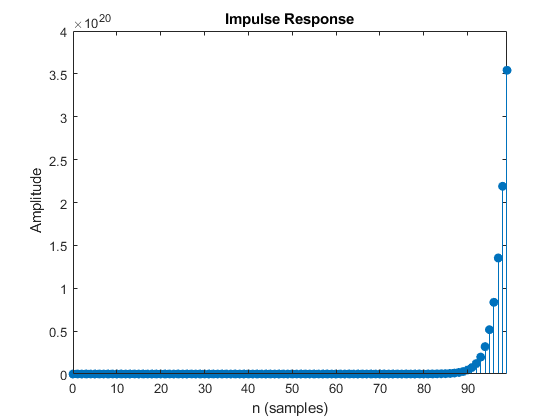

a = [1 -1 -1];
b = [1];
n = [1;100];

figure;
impz(b,a,100)

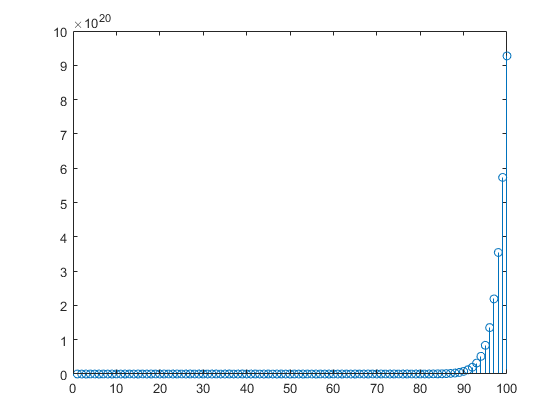

y = filter(b,a,ones(1,100));
figure;
stem(y)

**b) The Function is not decaying and continues and hence is not stable.**

**c)**

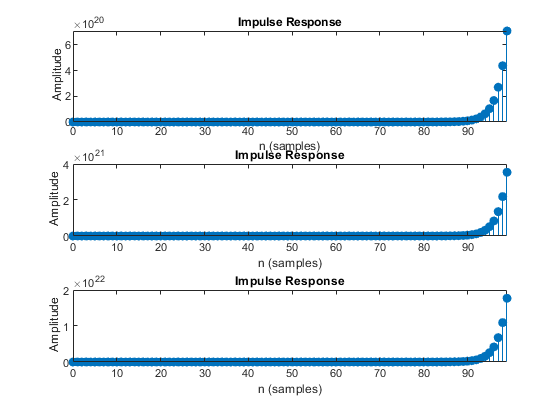

c  = [2];
d = [10];
e = [50];

figure;
subplot(3,1,1)
impz(c,a,100)
subplot(3,1,2)
impz(d,a,100)
subplot(3,1,3)
impz(e,a,100)

The shape of impulse response will remain the same however. the amplitude now increases at a greater exponential scale